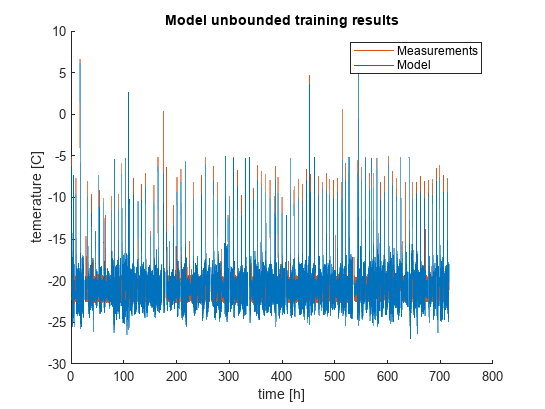

clear
load TrainingLargeDatasets.mat

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X_filtered(3,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y{i},'Color','#0072BD')
end
hold off
title('Model unbounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

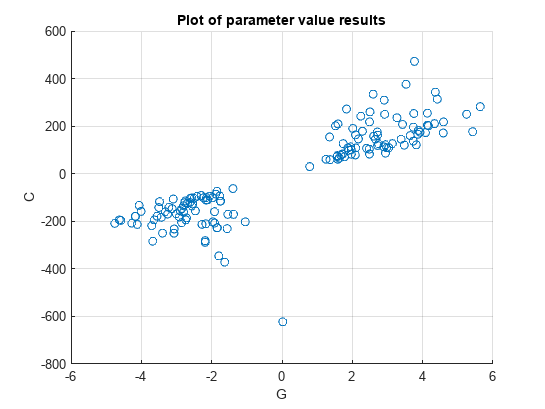

for i = 1:length(params)
resu(i,:)=params{i};
end

figure
plot3(resu(:,1),resu(:,2),resu(:,3),'o');
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results')
view(0,0)

clear all
count=1;
for i=1:length(resu)
    if all(resu(i,:) > [0,0,0]) 
        curvePoints(count,:)=resu(i,:);
        count=count+1;
    end
end

% Example data points
x = curvePoints(:,1)';
y = curvePoints(:,2)';
z = curvePoints(:,3)';

% Prepare data
[X, Y, Z] = prepareSurfaceData(x, y, z);

% Define the fit type (e.g., 'poly22' for a quadratic surface)
ft = fittype('poly22');

% Fit the model to the data
[fitresult, gof] = fit([X, Y], Z, ft);

% Display the fit coefficients
coefficients = coeffvalues(fitresult);
fprintf('Fitted surface equation: z = %.2fx^2 + %.2fy^2 + %.2fxy + %.2fx + %.2fy + %.2f\n', coefficients);

Fitted surface equation: z = -835.51x^2 + 314.63y^2 + 18.77xy + -24.26x + -2.21y + -0.11


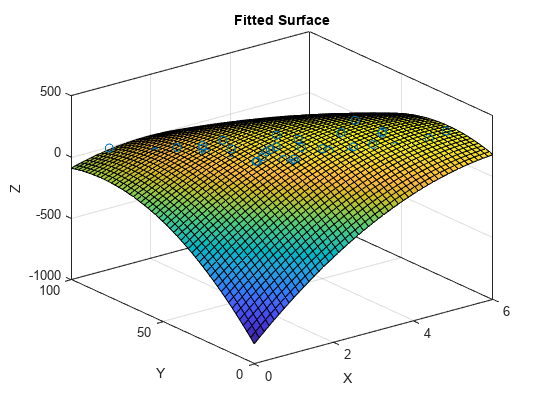


% Plot the original data and the fitted surface
figure;
plot3(x, y, z, 'o'); % Original data points
hold on;
h = plot(fitresult); % Fitted surface
% set(h, 'EdgeColor', 'none', 'FaceAlpha', 0.5);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Fitted Surface');
grid on;
hold off;

% Prepare data
[Z, X, Y] = prepareSurfaceData(z, x, y);

% Define the fit type (e.g., 'poly22' for a quadratic surface)
ft = fittype('poly22');

% Fit the model to the data
[fitresult, gof] = fit([Z, X], Y, ft);

% Display the fit coefficients
coefficients = coeffvalues(fitresult);
fprintf('Fitted surface equation: z = %.2fx^2 + %.2fy^2 + %.2fxy + %.2fx + %.2fy + %.2f\n', coefficients);

Fitted surface equation: z = 120.20x^2 + -0.04y^2 + -39.58xy + -0.00x + 0.02y + 3.54


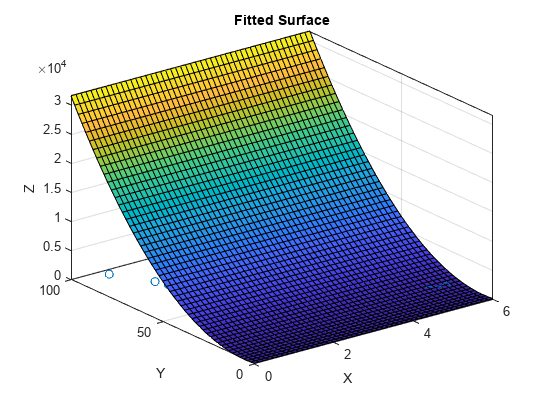


% Plot the original data and the fitted surface
figure;
plot3(x, y, z, 'o'); % Original data points
hold on;
h = plot(fitresult); % Fitted surface
% set(h, 'EdgeColor', 'none', 'FaceAlpha', 0.5);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Fitted Surface');
grid on;
hold off;

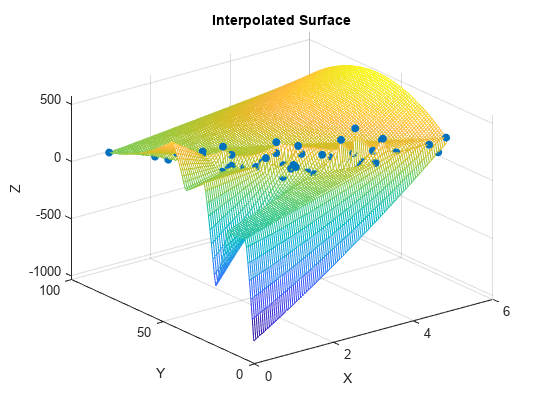

% Create the interpolant
F = scatteredInterpolant(x', y', z', 'natural', 'linear');

% Generate a grid to evaluate the interpolant
[xq, yq] = meshgrid(linspace(min(x), max(x), 100), linspace(min(y), max(y), 100));
zq = F(xq, yq);

% Plot the original data points
figure;
scatter3(x, y, z, 'filled');
hold on;

% Plot the interpolated surface
mesh(xq, yq, zq);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Interpolated Surface');
hold off;

% Prepare data for fitting (z and x as independent variables, y as dependent variable)
[X, Z, Y] = prepareSurfaceData(z, x, y);

% Define the fit type (e.g., 'poly22' for a quadratic surface)
ft = fittype('poly22');

% Fit the model to the data
[fitresult, gof] = fit([X, Z], Y, ft);

% Display the fit coefficients
coefficients = coeffvalues(fitresult);
fprintf('Fitted surface equation: y = %.2fz^2 + %.2fx^2 + %.2fzx + %.2fz + %.2fx + %.2f\n', coefficients);

Fitted surface equation: y = 120.20z^2 + -0.04x^2 + -39.58zx + -0.00z + 0.02x + 3.54


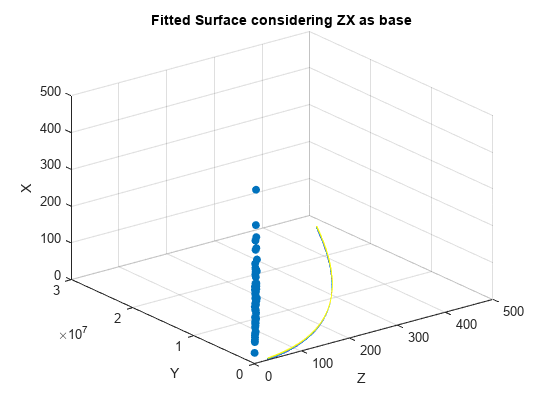


% Plot the original data and the fitted surface
figure;
scatter3(x, y, z, 'filled'); % Original data points
hold on;

% Create a meshgrid for the fitted surface
[zq, xq] = meshgrid(linspace(min(z), max(z), 100), linspace(min(x), max(x), 100));
yq = coefficients(1)*zq.^2 + coefficients(2)*xq.^2 + coefficients(3)*zq.*xq + coefficients(4)*zq + coefficients(5)*xq + coefficients(6);

% Plot the fitted surface
mesh(zq, yq, xq);
xlabel('Z');
ylabel('Y');
zlabel('X');
title('Fitted Surface considering ZX as base');
hold off;

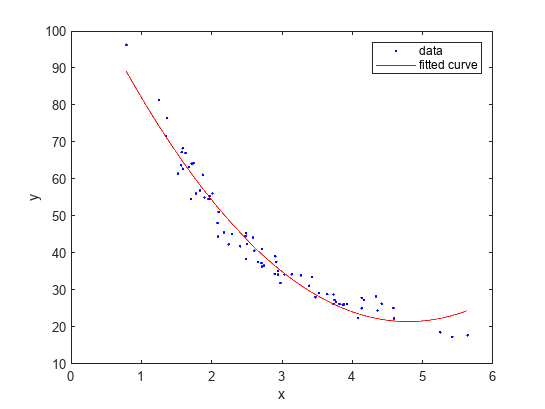

ft = fittype('poly2');
fitresult = fit(x',y',ft);
plot(fitresult,x,y)

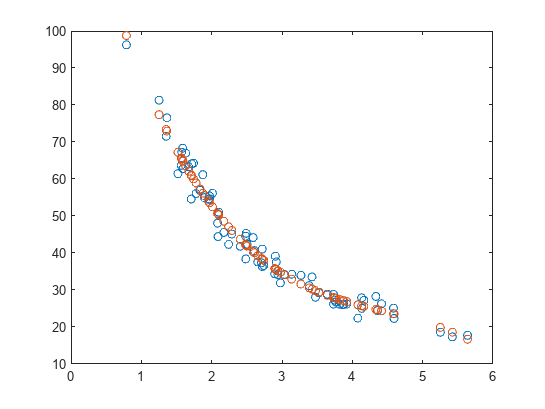

p = polyfit(x,y,3);
y1 = polyval(p,x);
figure
plot(x,y,'o')
hold on
plot(x,y1,'o')
hold off

% Define the fit type for a logarithmic fit
ft_log = fittype('a*log(x) + b');

% Fit the model to the data
[fitresult_log, gof_log] = fit(x', y', ft_log);


% Display the fit coefficients
coefficients_log = coeffvalues(fitresult_log);
fprintf('Logarithmic fit equation: y = %.2f*log(x) + %.2f\n', coefficients_log);

Logarithmic fit equation: y = -40.96*log(x) + 82.10


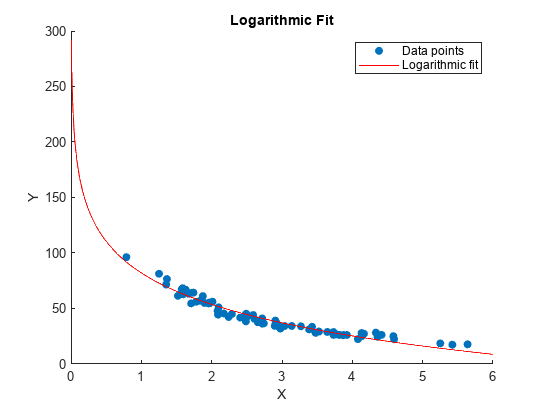


% Plot the original data and the fitted curve
figure;
scatter(x, y, 'filled'); % Original data points
hold on;
plot(fitresult_log, 'r-'); % Fitted logarithmic curve
xlabel('X');
ylabel('Y');
title('Logarithmic Fit');
legend('Data points', 'Logarithmic fit');
hold off;% Define the fit type for an exponential fit

ft_exp = fittype('a*exp(b*x)');

% Fit the model to the data
[fitresult_exp, gof_exp] = fit(x', y', ft_exp);


% Display the fit coefficients
coefficients_exp = coeffvalues(fitresult_exp);
fprintf('Exponential fit equation: y = %.2f*exp(%.2fx)\n', coefficients_exp);

Exponential fit equation: y = 122.83*exp(-0.41x)


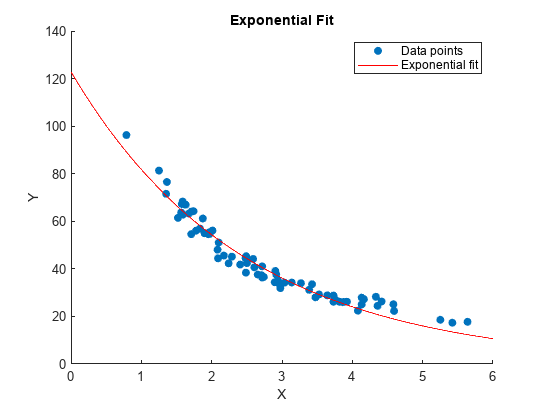


% Plot the original data and the fitted curve
figure;
scatter(x, y, 'filled'); % Original data points
hold on;
plot(fitresult_exp, 'r-'); % Fitted exponential curve
xlabel('X');
ylabel('Y');
title('Exponential Fit');
legend('Data points', 'Exponential fit');
hold off;